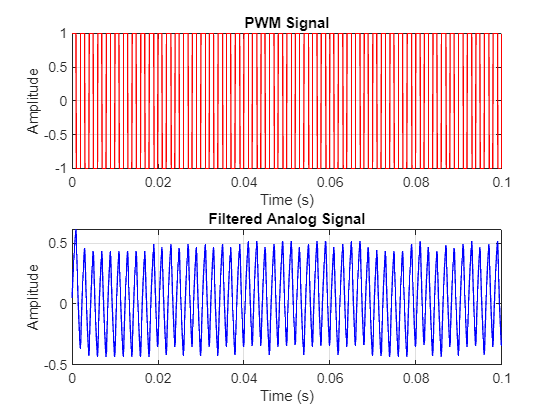

% PWM signal simulation
Fs = 10000; % Sampling frequency (10 kHz)
t = 0:1/Fs:0.1; % Time vector (0.1 seconds)
f_pwm = 500; % PWM frequency (500 Hz)
duty_cycle = 50; % Duty cycle in percentage
pwm = square(2 * pi * f_pwm * t, duty_cycle); % Generate PWM signal

% RC low-pass filter parameters
R = 10e3; % Resistance in ohms (10 kΩ)
C = 0.1e-6; % Capacitance in farads (0.1 µF)
fc = 1 / (2 * pi * R * C); % Cutoff frequency

% Filter the PWM signal
[b, a] = butter(1, fc / (Fs / 2)); % First-order Butterworth filter
filtered_signal = filter(b, a, pwm); % Apply the filter

% Plot results
figure;
subplot(2, 1, 1);
plot(t, pwm, 'r'); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('PWM Signal');

subplot(2, 1, 2);
plot(t, filtered_signal, 'b'); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title('Filtered Analog Signal');